% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% load individual vars into group cell arrays
%[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupIdxSmallPupilTrials, groupIdxLargePupilTrials, groupLongAxis, groupMeanPupilDiameterAllTrials, groupRunThresh, groupPupThresh] = makeGroupStruct();
% if no pup data:
[nGroup, nthVarsFilePaths, groupStimDetails, groupSubjData, groupSubjName, groupDate, groupTrialCond, groupNumPreStimFrames, groupNumPostStimFrames, groupIdxOnsetsMeetsCriteria, groupOnsetDf, groupPeakFrameIdx, groupStimOnsetFrame, groupBaselineIdx, groupBaselinedActIm, groupRoundXpts, groupRoundYpts, groupPTSdfof, groupMeanSpeedAllTrials, groupIdxRunTrials, groupIdxStatTrials, groupRunThresh] = makeGroupStruct_noPup();

nGroup = 3

% get stim conditions in order of trial & list of stim params to loop thru
% (This needs to be done new w/in the loop too each sess since the order of trialCond matters.. right now it's jsut to define cont & durat etc)
n = 1;
[durOrderedByTrialMeetCriteria,uniqueDurations,conOrderedByTrialMeetCriteria,uniqueContrasts,conAndDurOrderedByTrialMeetCriteria] = getStimParams4loops(n,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria);
% in preparation for making pixel wise figures of fluorescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend 

durs4Legend =     '6'    '7'



% GROUP MATRIX

% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n});
%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1

cont = 1:length(uniqueContrasts)

cont =      1     2     3     4     5     6     7



% LOCO NO PUP - makes group matricies, need this for all other figs/analyses
% stat group CRF matrix
state = 'loRun'

state = loRun

clear loRun_allSessAllPtsAllDurs_CRF
[loRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
% duration x contrasts x points x sessions
sizeloRunAllSessAllPtsAllDurs_CRF = size(loRun_allSessAllPtsAllDurs_CRF)

sizeloRunAllSessAllPtsAllDurs_CRF =      1     7     5     3


% run group CRF matrix
state = 'hiRun'

state = hiRun

clear hiRun_allSessAllPtsAllDurs_CRF
[hiRun_allSessAllPtsAllDurs_CRF] = CRF_byBehState_noPup(nGroup,state,groupStimDetails,groupTrialCond,groupIdxOnsetsMeetsCriteria,groupPTSdfof,groupPeakFrameIdx,groupBaselineIdx,groupIdxStatTrials,groupIdxRunTrials,visArea,durat,cont,conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations);
sizeHiRunAllSessAllPtsAllDurs_CRF = size(hiRun_allSessAllPtsAllDurs_CRF)

sizeHiRunAllSessAllPtsAllDurs_CRF =      1     7     5     3



% getting mean CRF ACROSS SESSIONS & STD ERR ACROSS SESSIONS 
% note: this code is roughtly the same as that w/in code from groupMeta.mlx wehere CRFs are calculated 
% and plotted from the data in, 
% except this code doesn't make fig w/in same function, and outputs the matrix to be plotted:
% LO BEH STATE
[loRun_mnCRF_acrossSess_AllDurAllPts,loRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(loRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_loRun_mnCRF_acrossSess_AllDurAllPts = size(loRun_mnCRF_acrossSess_AllDurAllPts)

size_loRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_loRun_stdErrCRF_acrossSess_allPts = size(loRun_stdErrCRF_acrossSess_allPts)

size_loRun_stdErrCRF_acrossSess_allPts =      5     7


% HI BEH STATE
[hiRun_mnCRF_acrossSess_AllDurAllPts,hiRun_stdErrCRF_acrossSess_allPts] = mean_CRF_AcrossSessions(hiRun_allSessAllPtsAllDurs_CRF,visArea,durat,cont);
size_hiRun_mnCRF_acrossSess_AllDurAllPts = size(hiRun_mnCRF_acrossSess_AllDurAllPts)

size_hiRun_mnCRF_acrossSess_AllDurAllPts =      5     7


size_hiRun_stdErrCRF_acrossSess_allPts = size(hiRun_stdErrCRF_acrossSess_allPts)

size_hiRun_stdErrCRF_acrossSess_allPts =      5     7


% loop vars for interp, calc C50, & plot
% which areas/stimulus parameters to loop over:
n = 1; % this is just to get the number of points
visArea = 1:length(groupRoundXpts{1,n})

visArea =      1     2     3     4     5


%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

%durat = 1:length(uniqueDurations)
durat = 1 % (durat = 1 means 100 ms in final set of expts)

durat = 1


%cont = 1:length(uniqueContrasts)
%cont = 7;

for d = durat
    
    clear lo_yi_interpedConsCurve_allPts{}
    clear lo_xi_isDf_higherRes_allPts{} 
    clear lo_C50_allPts
    clear lo_df_at_C50_allPts
    
    clear hi_yi_interpedConsCurve_allPts{}
    clear hi_xi_isDf_higherRes_allPts{} 
    clear hi_C50_allPts
    clear hi_df_at_C50_allPts
    
    for i = visArea

        % INTERP - LO beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_lo = loRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_lo;
        % resolution of interpolation 
        higherRes = 1/1000; 
        lo_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        lo_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,lo_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-min(ith_mnCRF_acrossSess_AllDurAllPts_lo);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        lo_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_lo)-halfOf_range;
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(lo_xi_isDf_higherRes>lo_df_at_C50));
        % use index to find associated interped cCON value
        lo_C50 = lo_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        % COLLECT LO VARS to plot
        lo_yi_interpedConsCurve_allPts{i,:} = lo_yi_interpedConsCurve;
        lo_xi_isDf_higherRes_allPts{i,:} = lo_xi_isDf_higherRes;
        lo_C50_allPts(i,:) = lo_C50;
        lo_df_at_C50_allPts(i,:) = lo_df_at_C50;
        
        % INTERP - HI beh state
        % take the ith CRF
        ith_mnCRF_acrossSess_AllDurAllPts_hi = hiRun_mnCRF_acrossSess_AllDurAllPts(i,:);
        % x is df vector
        x_is_df = ith_mnCRF_acrossSess_AllDurAllPts_hi;
        % resolution of interpolation 
        higherRes = 1/1000; 
        hi_xi_isDf_higherRes = min(x_is_df):higherRes:max(x_is_df);
        % the y input to inpterp() is the thing you want interpolated according to the resolution set above
        y_is_cons = uniqueContrasts;
        % interpolate contrast
        hi_yi_interpedConsCurve = interp1(x_is_df,y_is_cons,hi_xi_isDf_higherRes);
        % find con associated 1/2 max df/range value
        % find 1/2 max df
        % take the range of df (max df - min df)
        range = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-min(ith_mnCRF_acrossSess_AllDurAllPts_hi);
        % divide range by 2
        halfOf_range = range/2;
        % subtract 1/2 of range from max df to get the yvalue we want to query the interpolated contrast for
        hi_df_at_C50 = max(ith_mnCRF_acrossSess_AllDurAllPts_hi)-halfOf_range;
        % find C50 on interpolated curve
        % find first higher res df value greater than df_at_C50
        idx_df_hiRes_aboveC50 = min(find(hi_xi_isDf_higherRes>hi_df_at_C50));
        % use index to find associated interped cCON value
        hi_C50 = hi_yi_interpedConsCurve(1,idx_df_hiRes_aboveC50);
        % COLLECT VARS to plot
        hi_yi_interpedConsCurve_allPts{i,:} = hi_yi_interpedConsCurve;
        hi_xi_isDf_higherRes_allPts{i,:} = hi_xi_isDf_higherRes;
        hi_C50_allPts(i,:) = hi_C50;
        hi_df_at_C50_allPts(i,:) = hi_df_at_C50;

    end % end i loop
    
end % end d loop

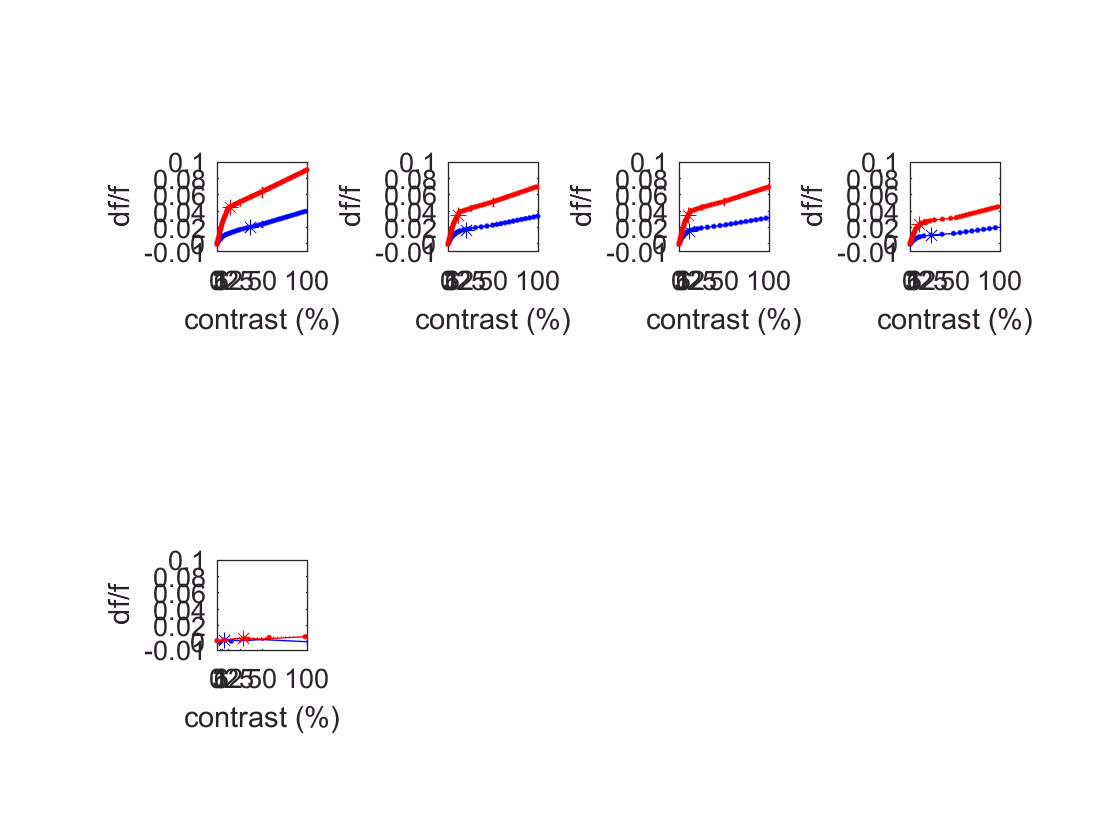

% PLOT BOTH beh STATES

% for FIGURE/Axes
yMax = 0.1;
yMin = -0.01;
yLimit = [yMin yMax];
yt = [-0.01 0 0.02 0.04 0.06 0.08 0.1];

%x_axis = [1:length(uniqueContrasts)];
xMax = max(uniqueContrasts);
xMin = min(uniqueContrasts);
xLimit = [xMin xMax];
xt=[0 0.03 0.06 0.12 0.25 0.5 1];
xtl = {'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'}; 
%xtl={'0'; '0.03' ; '0.06' ; '0.12' ; '0.25' ; '0.5'; '1'};


stateLegend = {'stat','run'};

figure

for i = visArea % leave out control area
    
    subplot(2,4,i)

    errorbar(uniqueContrasts,loRun_mnCRF_acrossSess_AllDurAllPts(i,:),loRun_stdErrCRF_acrossSess_allPts(i,:),'b')
    hold on 
    plot(lo_yi_interpedConsCurve_allPts{i},lo_xi_isDf_higherRes_allPts{i},'b:.')
    hold on 
    plot(lo_C50_allPts(i,:),lo_df_at_C50_allPts(i,:),'b*')
    
    hold on
    
    errorbar(uniqueContrasts,hiRun_mnCRF_acrossSess_AllDurAllPts(i,:),hiRun_stdErrCRF_acrossSess_allPts(i,:),'r')
    hold on 
    plot(hi_yi_interpedConsCurve_allPts{i},hi_xi_isDf_higherRes_allPts{i},'r:.')
    hold on 
    plot(hi_C50_allPts(i,:),hi_df_at_C50_allPts(i,:),'r*')
    
    ylim(yLimit) 
    xlim(xLimit)

    ylabel('df/f')
    xlabel('contrast (%)')
                        
    set(gca,'xtick',xt); 
    set(gca,'xticklabel',xtl);

    set(gca,'YTick',yt)
    
    axis square

end 

figure
Y = [lo_C50_allPts(1,:),hi_C50_allPts(1,:); lo_C50_allPts(2,:),hi_C50_allPts(2,:); lo_C50_allPts(3,:),hi_C50_allPts(3,:); lo_C50_allPts(4,:),hi_C50_allPts(4,:);]

Y =     0.3742    0.1527
    0.2071    0.1113
    0.1214    0.1064
    0.2357    0.1065


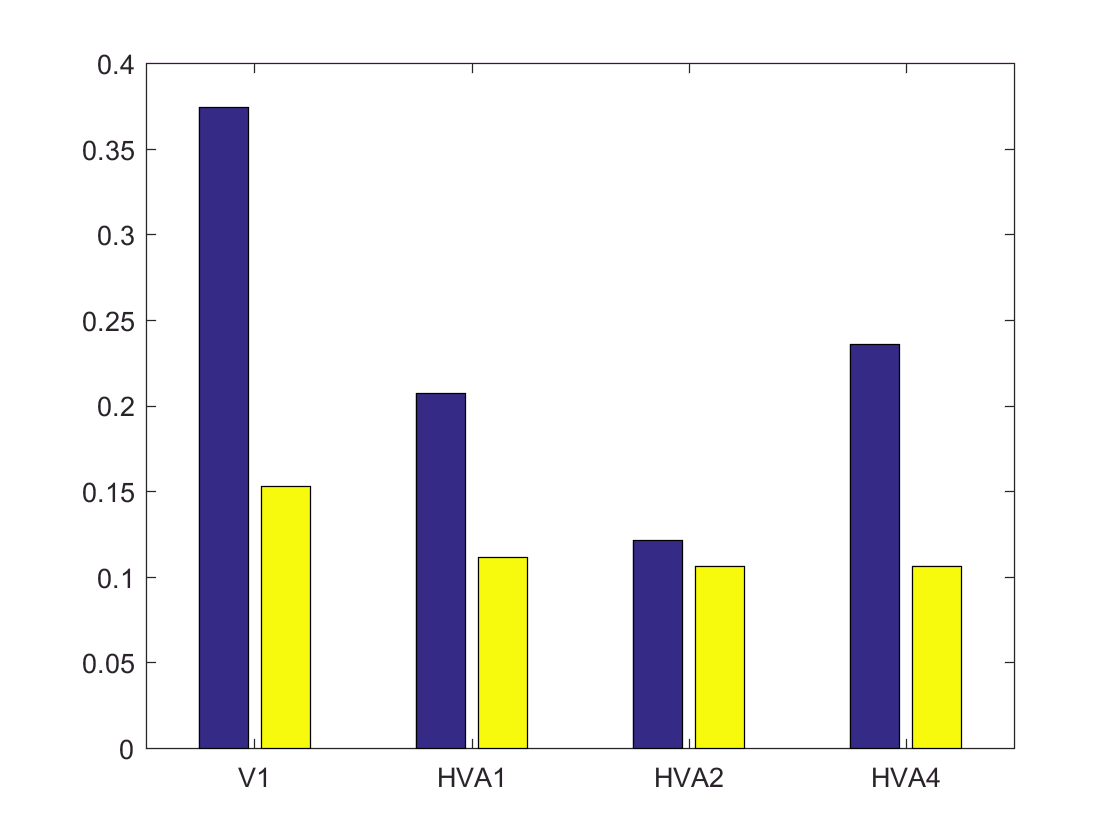

X = [1:4];
areaLabels = {'V1','HVA1','HVA2','HVA4'};
bar(X,Y)
set(gca,'xticklabel',areaLabels)

x = 1:13;
data = [37.6 24.5 14.6 18.1 19.5 8.1 28.5 7.9 3.3 4.1 7.9 1.9 4.3]';
errhigh = [2.1 4.4 0.4 3.3 2.5 0.4 1.6 0.8 0.6 0.8 2.2 0.9 1.5];
errlow  = [4.4 2.4 2.3 0.5 1.6 1.5 4.5 1.5 0.4 1.2 1.3 0.8 1.9];

bar(x,data)                

hold on

er = errorbar(x,data,errlow,errhigh);    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  

hold off